# HomeWork n.1 2023/24 Fontanella Vincenzo 0124002767

## Corso di Calcolo Numerico  (CdS Informatica) - prof. G.Giunta, prof. A. Galletti

**(scadenza: 5 aprile 2024, ore 23:59)**

Fissate due numeri interi $p$ e $q$  che sono, rispettivamente, il numero di caratteri del vostro nome e il numero di caratteri del vostro  cognome (usate il comando `p=length('vostroNome')` e analogamente per il vostro cognome). Usate questi due numeri per creare la seguente funzione:


$$e^{-0.6x} \cdot \left(cos \left(\frac {p \cdot x}{2}\right)\right)^2 +  \frac {q}{1+3x^2}sin(\pi x)-2$$


Tale funzione è la vostra **funzione di riferimento**. Scegliete un certo intervallo $[a,b]$ in modo che la vostra funzione di riferimento abbia **esattamente** 5 zeri, 2 minimi e 2 massimi in tale intervallo.

Consiglio 1: visualizzare ( `fplot`  e  `grid on) `il grafico della funzione di riferimento per esempio in [-4,1] e poi scegliere il sottointervallo $[a,b]$ in cui ci sono esattamente cinque zeri, due minimi e due massimi.  

Consiglio 2: ricordare che una funzione `f(x)` in Matlab ha come argomento un vettore `x` e quindi fare attenzione all'uso dell'operatorfe `.` (operazione componenente per componente).

In Matlab:

- definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete `funrif`;

- visualizzate il grafico della funzione di riferimento in $[a,b]$, specificando espicitamente quale intervallo avete scelto, per esempio utilizzando un tratto più spesso rispetto a quello dell'asse x (che deve essere esplicitamente visualizzato con una linea nera; usate i comandi `title` e `legend` per rendere più leggibile la figura;

- usate la function Matlab `fzero` per determinare i 5 zeri della vostra funzione di riferimento in $[a,b]$, e considerate i valori calcolati da `fzero` come le soluzioni esatte; 

- indicate sul grafico (comando `text`) con un pallino rosso i 5 zeri, il primo valore minimo e l'ascissa del primo minimo (detta *punto di minimo 1*) entrambi con un triangolino down blu, il secondo valore minimo e l'ascissa del secondo minimo (detta *punto di minimo 2*) entrambi con un triangolino down verde, il primo valore massimo e l'ascissa del primo massimo (detta *punto di massimo 1*) entrambi con un triangolino up blu, il secondo valore massimo e l'ascissa del secondo massimo (detta *punto di massimo 2*) entrambi con un triangolino up verde; usate i comandi `title` e `legend` per rendere più leggibile la figura;

- determinate un'approssimazione dei 5 zeri, usando il metodo Newton (nostra function `Newton`) per lo zero più a sinistra (primo zero) e per il secondo zero, il metodo di bisezione (nostra function `bisezione`) per il terzo  e quarto zero e il metodo delle Secanti (nostra function `Secanti`) per il quinto zero (consiglio: usare `funtool` oppure (meglio) il toolbox simbolico (comandi `syms` , `diff `e` matlabFunction`) per determinare l'espressione della derivata della funzione di riferimento), con un valore di `delta_ass` che garantisca, in tutti e 5 i casi, che la parte intera e le prime 6 cifre frazionarie siano corrette;

- considerate sia l'errore assoluto tra l'approssimazione di `Newton` e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con `Newton`), sia l'errore assoluto tra l'approssimazione della `bisezione` e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con `bisezione`), sia l'errore assoluto tra l'approssimazione di `Secanti `e la corrispondente soluzione esatta, e verificate che siano minori dell'accuratezza richiesta (`delta_ass`), commentando il loro valore; calcolate anche il residuo per ognuna delle cinque approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; solo guardando il grafico della funzione di riferimento, scrivere se, per ognuno dei cinque zeri, il problema appare bene o mal condizionato, spiegando qual è il significato di problema ben/mal condizionato;

- osservando il grafico della vostra funzione di riferimento nell'intervallo $[a,b]$e della bisettrice del primo quadrante, stabilite se ci sono punti fissi e determinate il loro numero; poi, senza usare la function `PFisso (`suggerimento: trasformate il problema di punto fisso in un problema equivalente di risoluzione di una equazione e usate opportunamente` fzero)`, calcolate una approssimazione dei due punti fissi più vicini all'estremo sinistro dell'intervallo, cioè più vicini ad $a$, visualizzateli sul grafico con  un quadrato nero e determinate i loro residui; dite se il metodo del punto fisso convergerebbe a tali punti fissi. Solo per i punti fissi per cui la teoria assicuri la convergenza (`suggerimento: `calcolate e visualizzate la derivata della funzione di riferimento nei due punti fissi considerati), calcolate tali punti fissi anche con la nostra function `PFisso`; commentate i risultati; usate i comandi `title` e `legend` per rendere più leggibile la figura;

- usate la function Matlab `fminbnd` per determinare i due punti di minimo e i due punti di massimo della vostra funzione di riferimento in $[a,b]$, con quattro chiamate del tipo: `fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`, e considerate i valori calcolati da `fminbnd` come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e dei due punti di massimo). Visualizzate sul grafico sia i punti di minimo e massimo, sia i valori minimi e massimi ivi assunti dalla funzione di riferimento;

- verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare `funtool` o (meglio)  il toolbox simbolico (comandi `syms` , `diff `e` matlabFunction`) per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione (in blu) sia il grafico della sua derivata (in rosso) [può essere utile usare anche la scalatura verticale della finestra grafica data dal comando `ylim([ymin, ymax])` ], e usando la `fzero` per calcolare tutti gli zeri della derivata nell'intervallo $[a,b]$; commentate i risultati ottenuti; usate i comandi `title` e `legend` per rendere più leggibile la figura;

- determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function `fminfibo`) per i due minimi, e il metodo di Golden search (nostra function `fmingolden`) per i due massimi, con un valore di `delta_ass` che garantisca che la parte intera e le prime 3 cifre frazionarie siano corrette; 

- considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (`delta_ass`), commentando i risultati.

ATTENZIONE: Fate attenzione affinché un uso non appropriato del `;` possa non far visualizzare i risultati richiesti nella relazione.

Scrivete una relazione che mostri tutto quanto richiesto nei punti precedenti. E' necessario che nella relazione tutti i risultati numerici siano commentati scrivendo esplicitamente a che cosa si riferisce ogni risultato numerico e, quando richiesto, se tale risultato è quello atteso. Usare il `format long` per tutti i risultati. Anche tutti grafici devono essere commentati. La relazione deve essere un LIVE SCRIPT, estensione `.mlx`, creato usando il LIVE EDITOR di Matlab. Il file deve essere eseguito (RUN) nella modalità che inserisce risultati e grafici all'interno del testo (e NON sulla destra).

Il file `.mlx` che contiene la relazione (eseguita con un RUN)  **deve essere caricato entro e non oltre il 5 aprile 2024, ore 23:59, sulla piattaforma TEAMS,**** (Attività del) Team del corso di Calcolo Numerico.  NON sono ammessi (pena esclusione dalla prova) file .zip o .rar . **

**Bisogna consegnare ****solamente**** il file .mlx**

**Pena ****esclusione dalla prova** bisogna:

- indicare all'inizo della relazione: Cognome, Nome e numero di matricola;

- denominare il file nel seguente modo: **HW1_Cognome_Nome.mlx**

p= length('Vincezo')

p =      7


q=length('Fontanella')

q =     10


1) Definizione della funzione: funref(x)

format long
funrif = @(x) exp(-0.6*x) .* (cos(p * x / 2)).^2 + (q ./ (1 + 3*x.^2)) .* (sin(pi*x)) - 2 

funrif = function_handle with value:
    @(x)exp(-0.6*x).*(cos(p*x/2)).^2+(q./(1+3*x.^2)).*(sin(pi*x))-2


funrifpermax = @(x) -exp(-0.6*x) .* (cos(p * x / 2)).^2 - (q ./ (1 + 3*x.^2)) .* (sin(pi*x)) + 2 

funrifpermax = function_handle with value:
    @(x)-exp(-0.6*x).*(cos(p*x/2)).^2-(q./(1+3*x.^2)).*(sin(pi*x))+2


2) Visualizzare grafico di funref con dovuti disegni di precisione e intervallo scelto = [-4,-1.9] e 3) Zeri per fzero()

figure
grid on
shg
hold on
fplot(funrif,[-4,1])

plot([-4,1],[0,0],'y')
plot([-4,-1.9],[0,0],'k','MarkerSize',30); 
val1= fzero(funrif,-4 )

val1 =   -3.911893497180281


val2= fzero(funrif,-3.5)

val2 =   -3.289570503191736


val3= fzero(funrif,-3)

val3 =   -2.962048134304669


val4= fzero(funrif,-2.5)

val4 =   -2.486927106170234


val5= fzero(funrif,-2)

val5 =   -1.991106643056403


appriniz = [val1,val2,val3,val4,val5]

appriniz =   -3.911893497180281  -3.289570503191736  -2.962048134304669  -2.486927106170234  -1.991106643056403


zfzero = zeros(1,5)

zfzero =      0     0     0     0     0


for i = 1:5
    zfzero(i)= fzero(funrif,appriniz(i)); end
title('Grafico della funzione funref e punti caratteristici')
plot(zfzero,zeros(size(zfzero)),'or','MarkerSize',15);  

4)determinazione di massimi e minimi nel grafico con dovuti triangoli

p_di_minimo1= fminbnd(funrif,-3.2,-3)

p_di_minimo1 =   -3.136281833367054


p_di_minimo2= fminbnd(funrif,-2.5,-2)

p_di_minimo2 =   -2.254321374461738


p_di_max1= fminbnd(funrifpermax,-4,-3.5)

p_di_max1 =   -3.612972855279997


p_di_max2= fminbnd(funrifpermax,-3,-2.5)

p_di_max2 =   -2.726064985822126


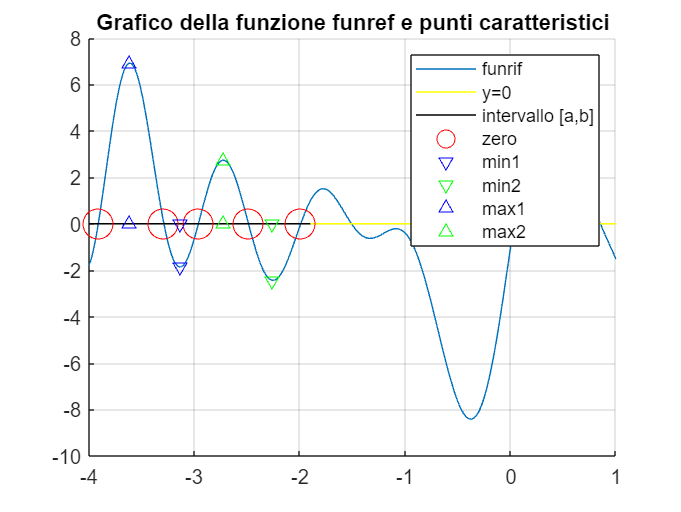

plot([p_di_minimo1,p_di_minimo1],[0,funrif(p_di_minimo1)],"vb")
plot([p_di_minimo2,p_di_minimo2],[0,funrif(p_di_minimo2)],"vg")
plot([p_di_max1,p_di_max1],[0,funrif(p_di_max1)],"^b")
plot([p_di_max2,p_di_max2],[0,funrif(p_di_max2)],"^g")
legend("funrif","y=0","intervallo [a,b]","zero","min1","min2","max1","max2") 
hold off

5)Calcolo degli zeri tramite approssimazioni di delta assoluto =1e-6

syms x
f= exp(-0.6*x)*(cos(p*x/2))^2+ q/(1+3*x^2)*sin(pi*x)-2

$$f = {\cos\left(\frac{7\,x}{2}\right)}^{2}\,{\mathrm{e}}^{-\frac{3\,x}{5}}+\frac{10\,\sin\left(\pi \,x\right)}{3\,x^{2}+1}-2$$

fprimo = diff(f)

$$fprimo = \begin{array}{l} \frac{10\,\pi \,\cos\left(\pi \,x\right)}{\sigma_{2}}-7\,\sigma_{1}\,\sin\left(\frac{7\,x}{2}\right)\,\sigma_{3}-\frac{3\,{\sigma_{1}}^{2}\,\sigma_{3}}{5}-\frac{60\,x\,\sin\left(\pi \,x\right)}{{\sigma_{2}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{7\,x}{2}\right)\\ \sigma_{2}=3\,x^{2}+1\\ \sigma_{3}={\mathrm{e}}^{-\frac{3\,x}{5}} \end{array}$$

f1=matlabFunction(fprimo)

f1 = function_handle with value:
    @(x)cos(x.*(7.0./2.0)).^2.*exp(x.*(-3.0./5.0)).*(-3.0./5.0)-cos(x.*(7.0./2.0)).*sin(x.*(7.0./2.0)).*exp(x.*(-3.0./5.0)).*7.0+(pi.*cos(x.*pi).*1.0e+1)./(x.^2.*3.0+1.0)-x.*sin(x.*pi).*1.0./(x.^2.*3.0+1.0).^2.*6.0e+1


approssimazione1= Newton(funrif,f1,-4,1e-6,30)

  -3.836462286831384   0.071894774067363   2.350249045791299

  -3.908357060898747   0.003509204492319   0.099699261369075

  -3.911866265391067   0.000027230097572   0.000761714058378

  -3.911893495488639   0.000000001691642   0.000000047314828



approssimazione1 =   -3.911893493796997


approssimazione2= Newton(funrif,f1,-3.3,1e-6,30)

  -3.289810783672154   0.000240139208309   0.005570049947196

  -3.289570644463844   0.000000141272059   0.000003272965666

  -3.289570503191785   0.000000000000049   0.000000000001129



approssimazione2 =   -3.289570503191834


approssimazione3= bisezione(funrif,-3,-2.8,1e-6)

approssimazione3 =   -2.962047958374024


approssimazione4= bisezione(funrif,-2.6,-2.3,1e-6)

approssimazione4 =   -2.486926937103272


approssimazione5= Secanti(funrif,-2.2,-1.8,1e-6,30)

approssimazione5 =   -1.991106311839858


6) Calcolo di errori assoluti e residui, con definizione di condizionamento con Secanti come caso speciale

err_ass1= abs(val1-approssimazione1)

err_ass1 =      3.383284319369295e-09


err_ass2= abs(val2-approssimazione2)

err_ass2 =      9.769962616701378e-14


err_ass3= abs(val3-approssimazione3)

err_ass3 =      1.759306451631915e-07


err_ass4= abs(val4-approssimazione4)

err_ass4 =      1.690669617637752e-07


err_ass5= abs(val5-approssimazione5)

err_ass5 =      3.312165446356374e-07


sprintf("Commento: 1e-7 è l'errore più grande senza usare un ciclo for. La precisione è maggiore perché delta_ass=1e-6")

ans = "Commento: 1e-7 è l'errore più grande senza usare un ciclo for. La precisione è maggiore perché delta_ass=1e-6"

residuo_ass1= abs(funrif(val1)-funrif(approssimazione1))

residuo_ass1 =      9.462966477080670e-08


residuo_ass2= abs(funrif(val2)-funrif(approssimazione2))

residuo_ass2 =      2.268407683914120e-12


residuo_ass3= abs(funrif(val3)-funrif(approssimazione3))

residuo_ass3 =      3.041672420156516e-06


residuo_ass4= abs(funrif(val4)-funrif(approssimazione4))

residuo_ass4 =      2.918618618563684e-06


residuo_ass5= abs(funrif(val5)-funrif(approssimazione5))  

residuo_ass5 =      4.172726532747362e-06


sprintf("Commento: l'approssimazione è acora almeno uguale a delta_ass")

ans = "Commento: l'approssimazione è acora almeno uguale a delta_ass"

% Definizione della funzione  (NOTA: ho provato a scrivere una funzione
% g(x) (handle) per definire la formula, ma mi dava sempre errore che la funzione
% non supportava il metodo.^-1, Ho anche provato con finverse, ma sempre lo
% stesso errore.)

g1=abs(f1(approssimazione1)).^-1

g1 =    0.035752892501008


g2=abs(f1(approssimazione2)).^-1

g2 =    0.043163348406428


g3=abs(f1(approssimazione3)).^-1

g3 =    0.057840096614863


g4=abs(f1(approssimazione4)).^-1

g4 =    0.057927051059760


g5=abs(f1(approssimazione5)).^-1

g5 =    0.079376553663859


sprintf("kf= abs(inversa di derivata di g(p)), ovvero la tendenza a distanziarsi dal risultato matematicamente perfetto (corretto). è quindi inversamente alla pendeza della funzione:più la pendenza è verticale, meglio condizionato è il problema")

ans = "kf= abs(inversa di derivata di g(p)), ovvero la tendenza a distanziarsi dal risultato matematicamente perfetto (corretto). è quindi inversamente alla pendeza della funzione:più la pendenza è verticale, meglio condizionato è il problema"

7) Calcolare l'intersezione tra bisettrice e funrif in [a,b] con ipotetica convergenza

figure
hold on
fplot(funrif,[-4,1])
grid on
plot([-4,1],[-4,1])
plot([-4,1],[0,0],'y')
plot([-4,-1.9],[0,0],'k','MarkerSize',30);
fpfisso= f - x

$$fpfisso = {\cos\left(\frac{7\,x}{2}\right)}^{2}\,{\mathrm{e}}^{-\frac{3\,x}{5}}-x+\frac{10\,\sin\left(\pi \,x\right)}{3\,x^{2}+1}-2$$

fpf= matlabFunction(fpfisso)

fpf = function_handle with value:
    @(x)-x+cos(x.*(7.0./2.0)).^2.*exp(x.*(-3.0./5.0))+(sin(x.*pi).*1.0e+1)./(x.^2.*3.0+1.0)-2.0


fpfisso1= diff(fpfisso) %% Si, so che è semplicemente -1 perché la derivata di x è 1, ma per prassi...

$$fpfisso1 = \begin{array}{l} \frac{10\,\pi \,\cos\left(\pi \,x\right)}{\sigma_{2}}-7\,\sigma_{1}\,\sin\left(\frac{7\,x}{2}\right)\,\sigma_{3}-\frac{3\,{\sigma_{1}}^{2}\,\sigma_{3}}{5}-\frac{60\,x\,\sin\left(\pi \,x\right)}{{\sigma_{2}}^{2}}-1\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{7\,x}{2}\right)\\ \sigma_{2}=3\,x^{2}+1\\ \sigma_{3}={\mathrm{e}}^{-\frac{3\,x}{5}} \end{array}$$

fpf1= matlabFunction(fpfisso1)

fpf1 = function_handle with value:
    @(x)cos(x.*(7.0./2.0)).^2.*exp(x.*(-3.0./5.0)).*(-3.0./5.0)-cos(x.*(7.0./2.0)).*sin(x.*(7.0./2.0)).*exp(x.*(-3.0./5.0)).*7.0+(pi.*cos(x.*pi).*1.0e+1)./(x.^2.*3.0+1.0)-x.*sin(x.*pi).*1.0./(x.^2.*3.0+1.0).^2.*6.0e+1-1.0


pfisso_numero_1= fzero(fpf,-2.32)

pfisso_numero_1 =   -2.304835706165678


pfisso_numero_2= fzero(fpf,-2.16)

pfisso_numero_2 =   -2.181926069436935


plot([pfisso_numero_1,pfisso_numero_2],[pfisso_numero_1,pfisso_numero_2],'squarek') % NOTA: premi run qui, se non hai abbastanza ram per mostrare il grafico
residuo_pfisso1= abs(pfisso_numero_1-funrif(pfisso_numero_1))

residuo_pfisso1 =      2.664535259100376e-15


residuo_pfisso2= abs(pfisso_numero_2-funrif(pfisso_numero_2))

residuo_pfisso2 =      4.440892098500626e-16


convergenza1=abs(fpf1(pfisso_numero_1)) %% c= abs(g'(p))<1

convergenza1 =    6.197960136246070


convergenza2=abs(fpf1(pfisso_numero_2))

convergenza2 =    5.778207475858258


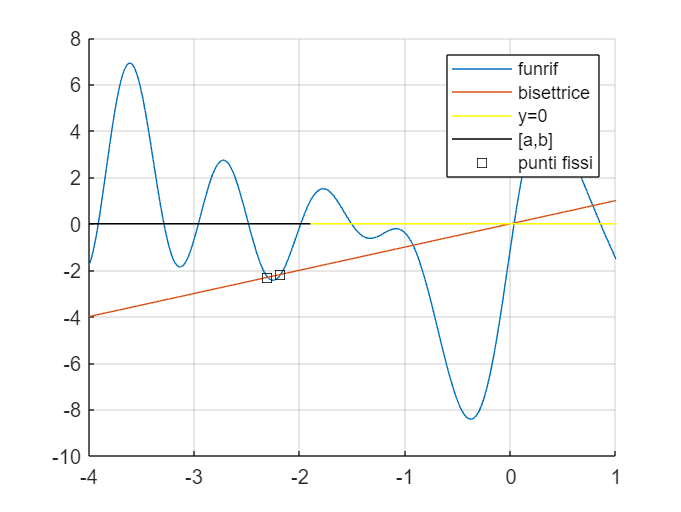

legend("funrif","bisettrice","y=0","[a,b]","punti fissi")

sprintf("Entrambe le derivate di tali funzioni, le quali" + ...
    " rappresentano il tasso di convergenza, hanno un valore maggiore di 1," + ...
    " quindi non convergono. L'ideale sarebbe porre  la fpfisso1 uguale a zero, dividerle per il seno, il coseno o l'exp per semplificarla " + ...
    "porle sopra un denominatore di alto grado nella speranza di garantire un risultato minore di 1 " + ...
    "e calcolarlo con il metodo del punto fisso, " + ...
    "ma non scherzo quando dico che dal 7o punto in poi il laptop " + ...
    "mi è crashato 4 volte, e preferirei tenermi in pari con  gli studenti" + ...
    " che nemmeno devono fare questo esercizio perché hanno nominativi più" + ...
    " corti. Grazie della pazienza e buon continuo della lettura.")

ans = "Entrambe le derivate di tali funzioni, le quali rappresentano il tasso di convergenza, hanno un valore maggiore di 1, quindi non convergono. L'ideale sarebbe porre  la fpfisso1 uguale a zero, dividerle per il seno, il coseno o l'exp per semplificarla porle sopra un denominatore di alto grado nella speranza di garantire un risultato minore di 1 e calcolarlo con il metodo del punto fisso, ma non scherzo quando dico che dal 7o punto in poi il laptop mi è crashato 4 volte, e preferirei tenermi in pari con  gli studenti che nemmeno devono fare questo esercizio perché hanno nominativi più corti. Grazie della pazienza e buon continuo della lettura."


%% fun(x)= x e fun(x) - x= 0


8) Zeri della derivata

p_di_minimo1= fminbnd(funrif,-3.2,-3,optimset('Tolx',1e-10))

p_di_minimo1 =   -3.136280634910967


p_di_minimo2= fminbnd(funrif,-2.5,-2,optimset('Tolx',1e-10))

p_di_minimo2 =   -2.254329050988487


p_di_max1= fminbnd(funrifpermax,-4,-3.5,optimset('Tolx',1e-10))

p_di_max1 =   -3.612964428556616


p_di_max2= fminbnd(funrifpermax,-3,-2.5,optimset('Tolx',1e-10))

p_di_max2 =   -2.726062711764764


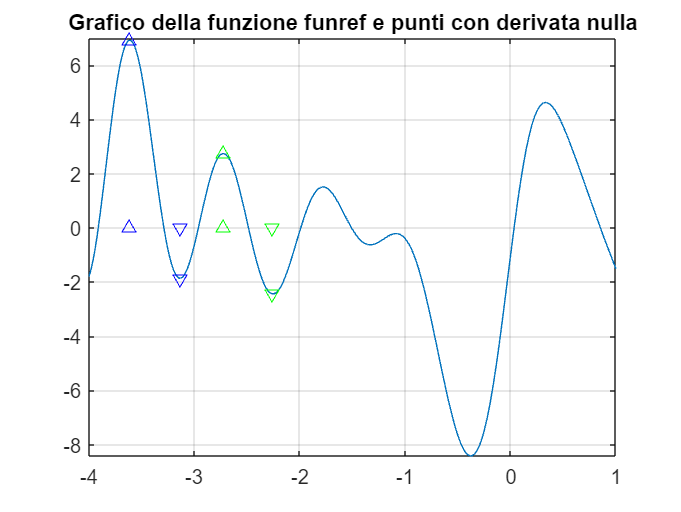

figure
fplot(funrif,[-4,1])
grid on
shg
hold on

title('Grafico della funzione funref e punti con derivata nulla')
plot([p_di_minimo1,p_di_minimo1],[0,funrif(p_di_minimo1)],"vb")
plot([p_di_minimo2,p_di_minimo2],[0,funrif(p_di_minimo2)],"vg")
plot([p_di_max1,p_di_max1],[0,funrif(p_di_max1)],"^b")
plot([p_di_max2,p_di_max2],[0,funrif(p_di_max2)],"^g") 
hold off

9) Verifica degli zeri della derivata  (verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare `funtool` o (meglio)  il toolbox simbolico (comandi `syms` , `diff `e` matlabFunction`) per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione (in blu) sia il grafico della sua derivata (in rosso) [può essere utile usare anche la scalatura verticale della finestra grafica data dal comando `ylim([ymin, ymax])` ], e usando la `fzero` per calcolare tutti gli zeri della derivata nell'intervallo $[a,b]$; commentate i risultati ottenuti; usate i comandi `title` e `legend` per rendere più leggibile la figura;)

verificaminD1=f1(p_di_minimo1)    

verificaminD1 =     -6.833904309389016e-07


verificaminD2=f1(p_di_minimo2)

verificaminD2 =     -1.112476246678540e-07


verificamaxD1=f1(p_di_max1)

verificamaxD1 =      3.112259663873296e-07


verificamaxD2=f1(p_di_max2) %%Tutti molto vicini a zero, come derivata nulla vuole

verificamaxD2 =     -6.985553323846094e-07


figure 
hold on 
title( "Calcolo dei massimi e minimi")
fplot(funrif,[-4,1],'b')
fplot(f1,[-4,1],'r')
plot([-4,1],[0,0],'y')
plot([-4,-1.9],[0,0],'k','MarkerSize',30); 
Dnulla1= fzero(f1,-3.5)      %% I risultati rispecchiano il grafico

Dnulla1 =   -3.612964427115711


Dnulla2= fzero(f1,-3.1)

Dnulla2 =   -3.136280630566123


Dnulla3= fzero(f1,-2.8)

Dnulla3 =   -2.726062717408795


Dnulla4= fzero(f1,-2.2)

Dnulla4 =   -2.254329049896020


plot([Dnulla1,Dnulla2,Dnulla3,Dnulla4],[0,0,0,0],'xk')


10) Minimi e massimi per tasso di apprendimento ( Fibonacci e phi) (determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function `fminfibo`) per i due minimi, e il metodo di Golden search (nostra function `fmingolden`) per i due massimi, con un valore di `delta_ass` che garantisca che la parte intera e le prime 3 cifre frazionarie siano corrette; )

Fibominimo1= fminfibo(funrif,-3.4,-3.1,1e-3)

Fibominimo1 =   -3.135416666666667


Fibominimo2= fminfibo(funrif,-2.5,-2.2,1e-3)

Fibominimo2 =   -2.254166666666666


Goldenmax1= fmingolden(funrifpermax,-3.7,-3.4,1e-3)

Goldenmax1 =   -3.612927022752083


Goldenmax2= fmingolden(funrifpermax,-3,-2.5,1e-3)

Goldenmax2 =   -2.725904704055060


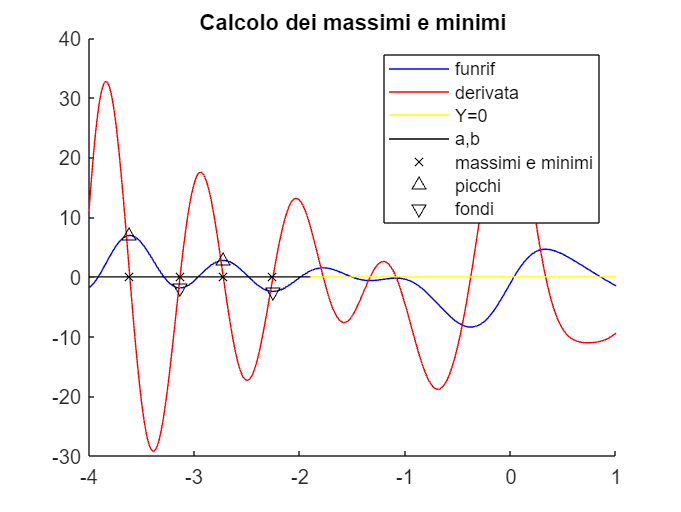

plot([Goldenmax1,Goldenmax2],[funrif(Goldenmax1), funrif(Goldenmax2)],'^k')
plot([Fibominimo1,Fibominimo2],[funrif(Fibominimo1), funrif(Fibominimo2)],'vk')
legend('funrif','derivata','Y=0','a,b','massimi e minimi','picchi','fondi') 

11)Errori assoluti e residui (considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (`delta_ass`), commentando i risultati.)

Err_Fibo1=abs(Fibominimo1-p_di_minimo1)

Err_Fibo1 =      8.639682443001284e-04


Err_Fibo2=abs(Fibominimo2-p_di_minimo2)

Err_Fibo2 =      1.623843218210297e-04


Err_Golden1=abs(Goldenmax1-p_di_max1)

Err_Golden1 =      3.740580453248654e-05


Err_Golden2=abs(Goldenmax2-p_di_max2)

Err_Golden2 =      1.580077097034227e-04


sprintf('Accuratezza minima sempre rispettata, in quanto Err_fibo1(peggiore)<delta_ass(1e-3)')

ans = 'Accuratezza minima sempre rispettata, in quanto Err_fibo1(peggiore)<delta_ass(1e-3)'